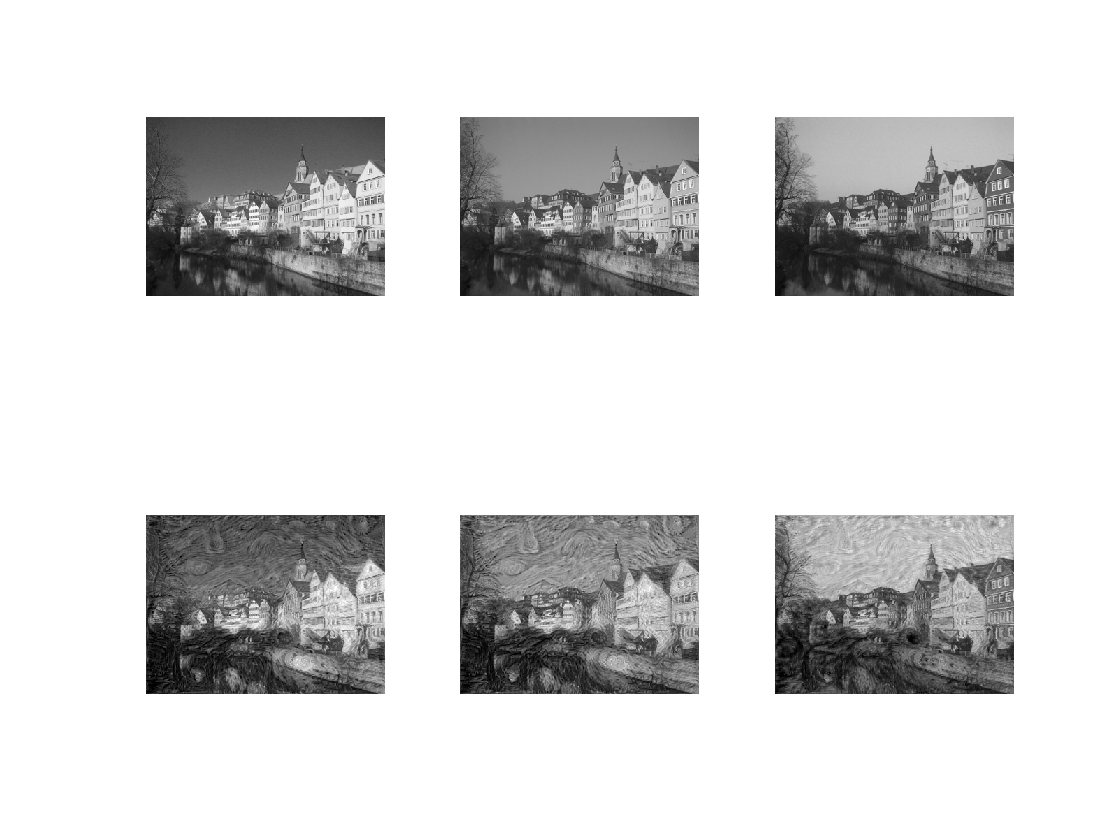

clear
close all;
img = imread('../img/tubingen_rs.png');
styled = imread('../img/tubingen_starry.png');
subplot(2,3,1);
imshow(img(:,:,1));
subplot(2,3,2);
imshow(img(:,:,2));
subplot(2,3,3);
imshow(img(:,:,3));
subplot(2,3,4);
imshow(styled(:,:,1));
subplot(2,3,5);
imshow(styled(:,:,2));
subplot(2,3,6);
imshow(styled(:,:,3));

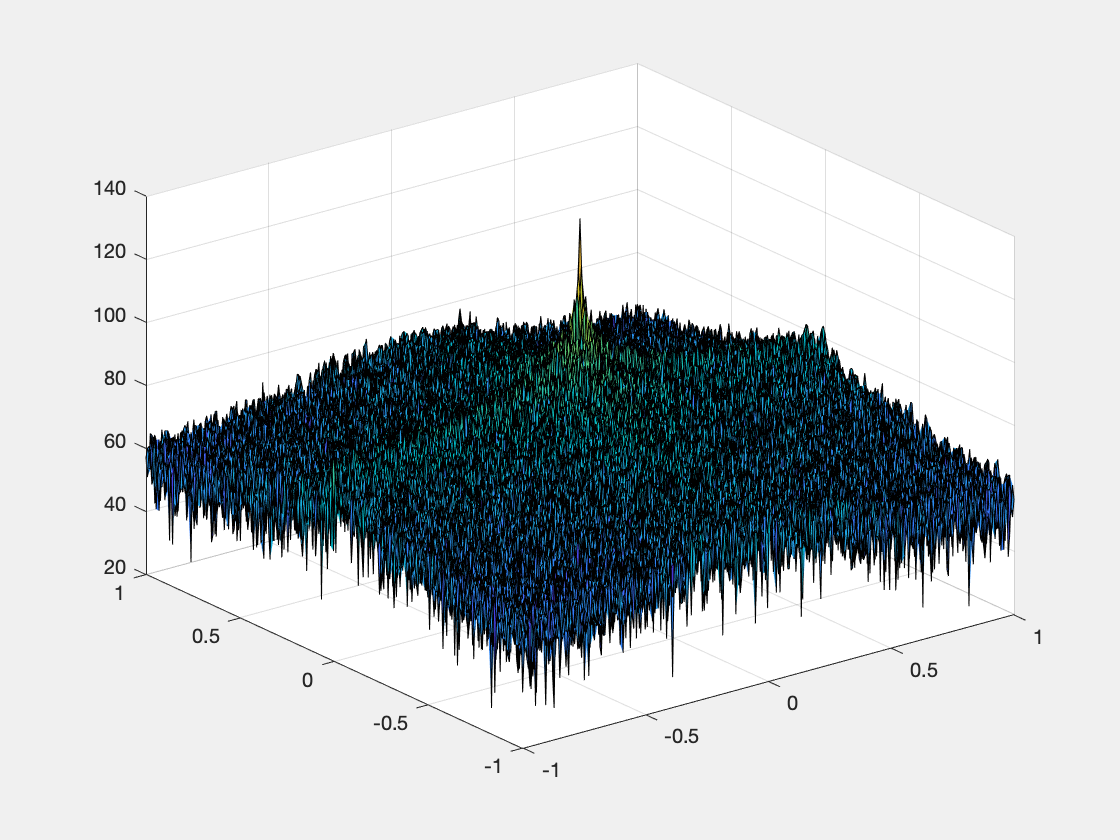

chan = img(:,:,1);
sty_chan = styled(:,:,1);
A = fftshift(fft2(chan));
M = size(A,2);
N = size(A,1); 
[x y] = meshgrid(linspace(-M/2, M/2, M), linspace(-N/2, N/2, N));
figure;
surf(x*2/M, y*2/N, 20*log10(abs(A(:,:,1))));
rotate3d on;

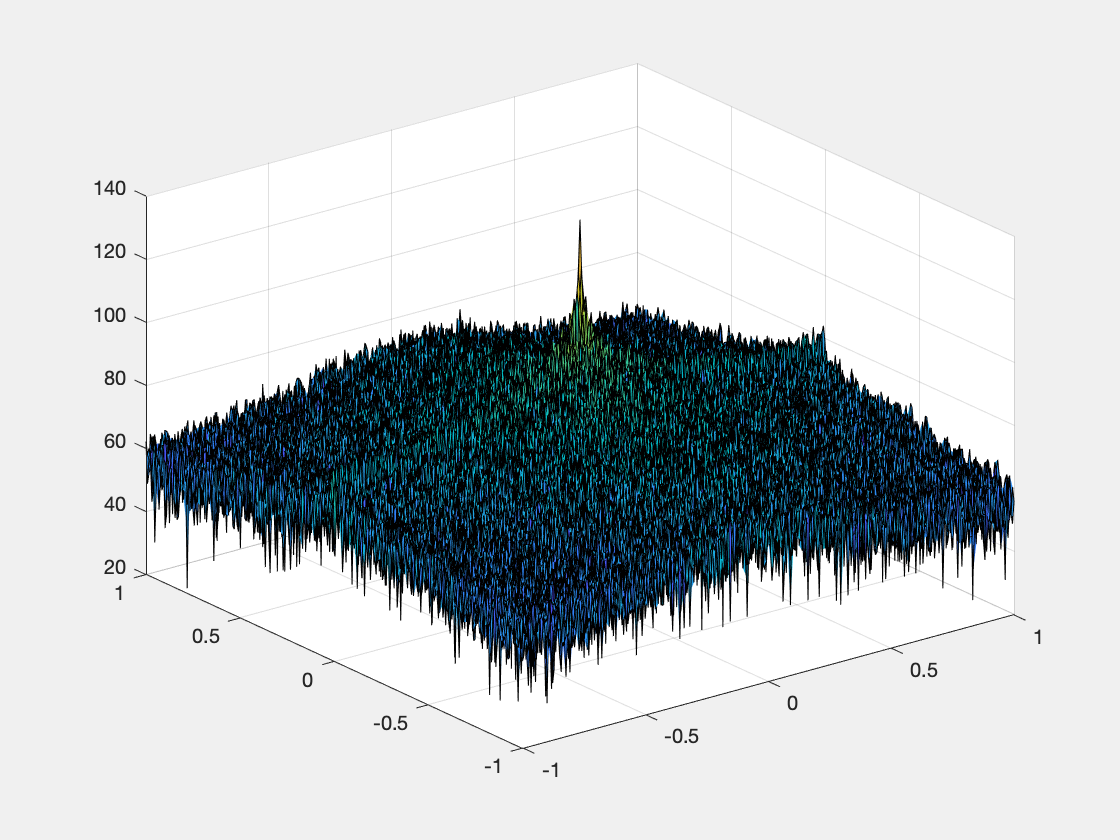

figure;
B = fftshift(fft2(sty_chan));
M = size(B,2);
N = size(B,1); 
[x y] = meshgrid(linspace(-M/2, M/2, M), linspace(-N/2, N/2, N));
figure;
surf(x*2/M, y*2/N, 20*log10(abs(B(:,:,1))));
rotate3d on;

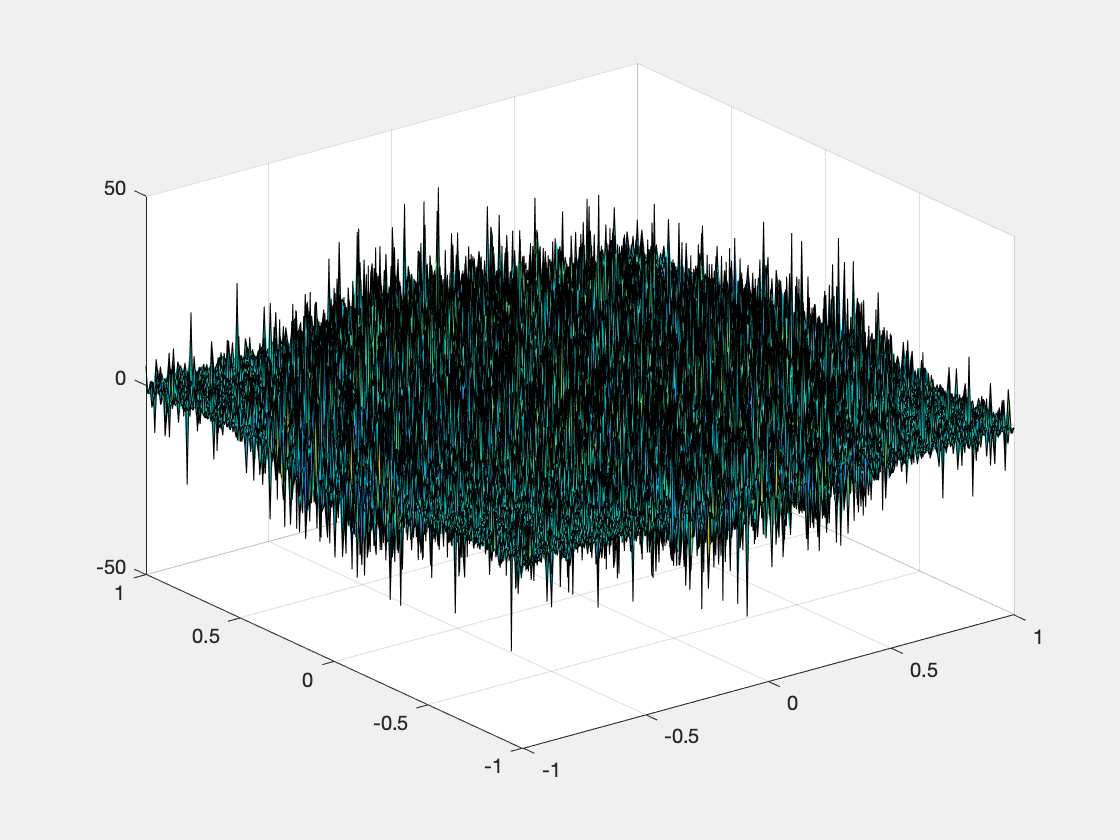


% figure(3)
tmp = 20*log10(abs(B(:,:,1)./A(:,:,1)));
figure;
surf(x*2/M, y*2/N, tmp);
rotate3d on;

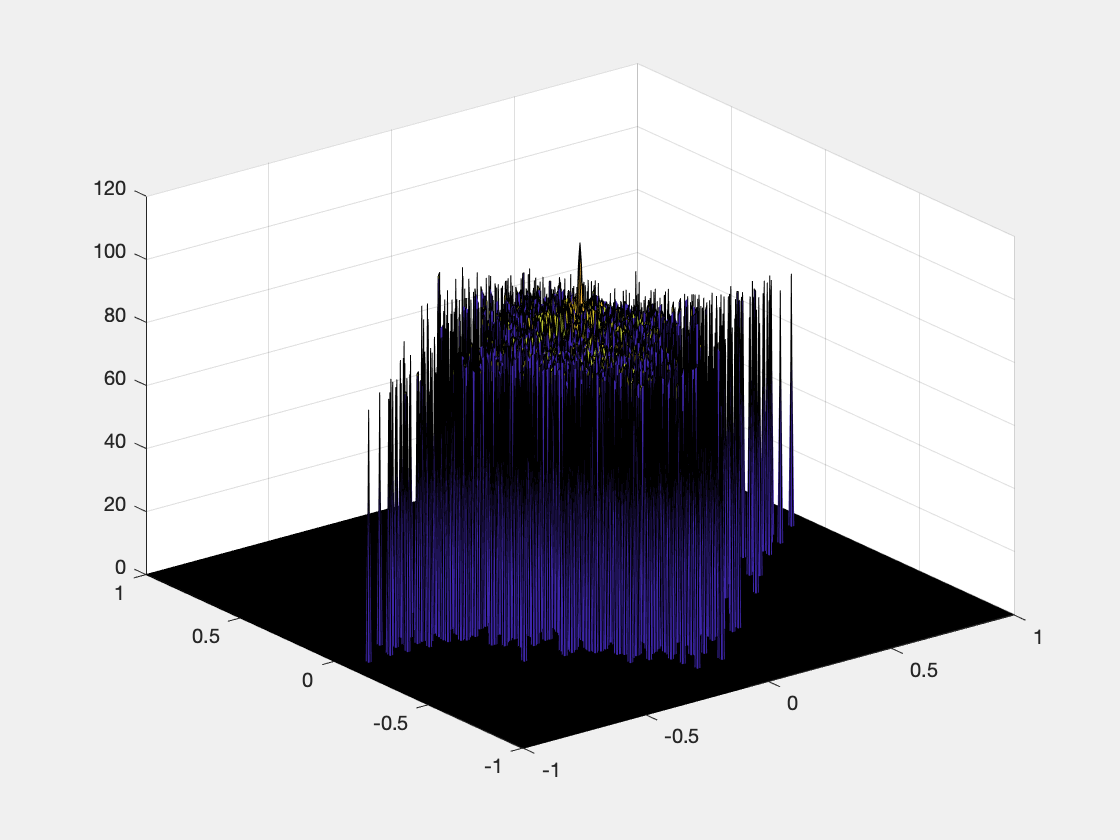

tmp = 20*log10(abs(B(:,:,1)-A(:,:,1)));
tmp(tmp<80) = 0;
figure;
surf(x*2/M, y*2/N, tmp);
rotate3d on;

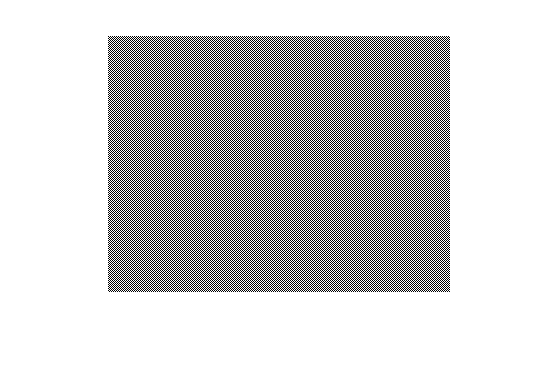

% figure(3);
% tmpf = B(:,:,1)./A(:,:,1);
% tmpf(abs(20*log10(tmpf)) < 30) = 1;
% F = A.*tmpf;
% final_im = ifftshift(ifft2(F));
% imshow(final_im);

% % view(2);
